## Homogeneous coordinates 

Equations of linear geometric transformations have concise equations in which the transformation can be represented by a single matrix. For instance, the following transformation that maps vector ${\bf x}$ onto vector ${\bf x}^\prime$: 


$${\bf x}^\prime = SR\,{\bf x},
$$


where $S$ is a scaling matrix and $R$ is a rotation matrix. Since both $S$ and $R$ are linear transformations, so the composition $SR$. Here, the product $SR$ also yields a single matrix. 

This compact form of the transformation matrix simplifies both their notation and computation. For example, we can change the order of the transformations by simply changing the order of multiplication, i.e.:  


$${\bf x}^{\prime\prime} = RS\,{\bf x},
$$


or we can calculate the inverse of the transformation directly, i.e., the inverse of ${\bf x}^\prime = SR\,{\bf x}$ can be written as: 

${\bf x} = (SR)^{-1}\,{\bf x}^\prime = (R^{-1}S^{-1})\,{\bf x}^\prime$.

However, this compact notation is broken if the transformation includes a translation, i.e., for affine transformations. An affine transformation includes a linear component and a translation component and is written as follows:

${\bf x}^\prime = A{\bf x} + {\bf t} 
$.  

In 2-D, the matrix form of the affine transformation can be written explicitly as: 


$$\left[\begin{array}{c}
		x^\prime \\
		y^\prime
\end{array}\right] = 
\left[\begin{array}{c}
		a_1 & a_2 \\
		a_3 & a_4
\end{array}\right]
\left[\begin{array}{c}
    x \\    
    y
\end{array}\right]
+
\left[\begin{array}{c}
    t_x \\    
    t_y
\end{array}\right]$$


Now, the transformation notation combines a multiplication followed by a addition. It can no longer be represented by a (single) matrix.  

## Example:

% Scaling
S = [ 2 0;
      0 1 ]

S =      2     0
     0     1



% Rotation
theta = pi/8; 
R = [ cos(theta) -sin(theta);
      sin(theta)  cos(theta) ];

% Translation part of the affine transformation
t = [ 2; 
      3]

t =      2
     3


## The shape to be transformed

Rectangle given by four vertices

px = [0 4 4 0];   % x-coords
py = [0 0 2 2];   % y-coords  
disp('Input shape')

Input shape


X  = [px;py]        % Matrix containing the 2-D points.

X =      0     4     4     0
     0     0     2     2


## Apply transformation to shape

The transformation we will apply to the rectangle is a Rotation followed by a Scaling and then a Translation, i.e.: 

${\bf x}^\prime = (SR)\,{\bf x} + {\bf t}
$.

disp('Transformed shape')

Transformed shape


X_p = (S * R) * X + t 

X_p =     2.0000    9.3910    7.8603    0.4693
    3.0000    4.5307    6.3785    4.8478


## Display shapes

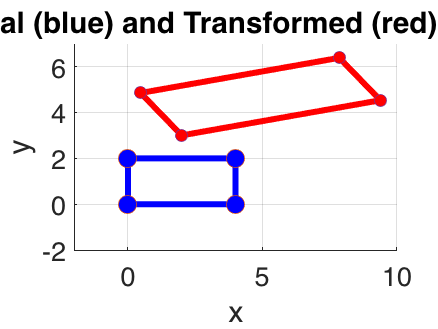

figure;
hold on;
axis([ -2 10 -2 7 ] );
% Repeating the first vertex to close polygon lines
plot([X(1,:) X(1,1)], [X(2,:) X(2,1)], 'b-', 'linewidth',4);
plot([X(1,:) X(1,1)], [X(2,:) X(2,1)], 'o', 'MarkerSize', 12, 'MarkerFaceColor','b')
xlabel('x','FontSize',30);
ylabel('y','FontSize',30);
set(gca, 'fontsize',18);
set(gcf, 'color', 'w' );
title('Original (blue) and Transformed (red) Shapes ');
% Show the transformed points
plt = plot([X_p(1,:), X_p(1,1)], [X_p(2,:), X_p(2,1)], 'r-', 'linewidth',4);
plot([X_p(1,:), X_p(1,1)], [X_p(2,:), X_p(2,1)], 'o', 'MarkerSize', 8, 'MarkerFaceColor','r');
% Plot transformed shape transparent
plt.Color(4) = 0.5;
grid on;

To see how the inclusion of the translation further complicates the matrix notation, let us calculate the inverse of the affine transformation used in the above example. The inverse is given by:  

${\bf x} = (SR)^{-1}\left({\bf x}^\prime - {\bf t}\right) = R^{-1}S^{-1}\left({\bf x}^\prime - {\bf t}\right) = R^{-1}S^{-1}{\bf x}^\prime - R^{-1}S^{-1}{\bf t} $.

We can use this equation to go from the red shape back to the blue shape. 

## Example using the inverse affine transformation

In this example, we do exactly that but we will plot the transformed shape in green color. 

% Input shape is the transformed shape from the previous example
disp('Input shape')

Input shape


X_p

X_p =     2.0000    9.3910    7.8603    0.4693
    3.0000    4.5307    6.3785    4.8478


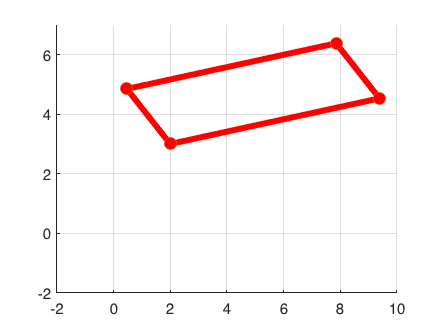


figure
axis([ -2 10 -2 7 ] );
hold on;
% Show the transformed points
plt = plot([X_p(1,:), X_p(1,1)], [X_p(2,:), X_p(2,1)], 'r-', 'linewidth',4);
plot([X_p(1,:), X_p(1,1)], [X_p(2,:), X_p(2,1)], 'o', 'MarkerSize', 8, 'MarkerFaceColor','r');
% Plot transformed shape transparent
%plt.Color(4) = 0.5;
grid on;

disp('This is the shape resulting from the inverse affine transformation')

This is the shape resulting from the inverse affine transformation


% Calculate the shape produced by the inverse affine 
Xi = inv(R) * inv(S) * X_p - inv(R) * inv(S) * t 

Xi =          0    4.0000    4.0000    0.0000
         0    0.0000    2.0000    2.0000


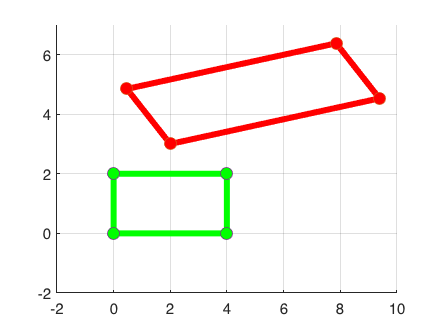


hold on;
% Show the transformed points
plot([Xi(1,:), Xi(1,1)], [Xi(2,:), Xi(2,1)], 'g-', 'linewidth',4);
plot([Xi(1,:), Xi(1,1)], [Xi(2,:), Xi(2,1)], 'o', 'MarkerSize', 8, 'MarkerFaceColor','g');
% Plot transformed shape transparent
grid on;

## Homogeneous coordinates

We can make the matrix notation of affine transformations more concise by using **Homogeneous coordinates** (or projective coordinates) instead of Cartesian coordinates. This is done by augmenting the Cartesian coordinates with an extra non-zero coordinate value, which is usually chosen to be 1.

To convert the original points from Cartesian to Homogeneous coordinates, we simply add the original vector by adding 1 as an extra coordinate (i.e., dimension), i.e.: 


$$\left[\begin{array}{c}
		x \\
		y 
\end{array}\right] 
\rightarrow
\lambda\left[\begin{array}{c}
		x \\
		y \\
                1
\end{array}\right]$$


This is still a 2-D point but it is now represented by 3 instead of 2 coordinates. Here, all we are doing to convert from Cartesian coordinates to homogeneous coordinates is to augment the original vector by adding $\lambda\neq0$ as an extra coordinate. 

To convert homogenous coordinates back to Cartesian, we need only to divide the homogeneous coordinates as follows: 


$$\lambda\left[\begin{array}{c}
		x \\
		y \\
                1
\end{array}\right]
\rightarrow
\left[\begin{array}{c}
		x / \lambda\\
		y / \lambda
\end{array}\right] 
$$


The simplest and most common choice is to set $\lambda=1$, i.e.: 

$\left[\begin{array}{c}
		x \\
		y 
\end{array}\right] 
\rightarrow
\left[\begin{array}{c}
		x \\
		y \\
                1
\end{array}\right]$.

Because, we augmented the vectors, we must also augment the transformations. 

## The affine transformation in homogeneous coordinates

Let us now repeat the examples of affine transformations used previously in these notes but this time using homogeneous coordinates. The 2-D affine transformation in homogeneous coordinates is given by: 

$\left[\begin{array}{c}
		x^\prime \\
		y^\prime \\
                 1
\end{array}\right] = 
\left[\begin{array}{c}
		a_1 & a_2  & t_x\\
		a_3 & a_4  & t_y\\
                  0  &   0    &   1
\end{array}\right]
\left[\begin{array}{c}
    x \\    
    y \\
    1
\end{array}\right]$.

This single matrix in homogeneous coordinates incorporate both the linear part of the affine and its translation. In homogeneous coordinates the scaling matrix is: 

$S_h = \left[\begin{array}{c}
		s_x & 0  &     0\\
		0 & s_y  &  0\\
                  0  &   0    &   1
\end{array}\right]$,

and the rotation is given by: 

$R_h= \left[\begin{array}{c}
		\cos\theta & -\sin\theta & 0 \\
		\sin\theta & \cos\theta & 0 \\
		0 & 0 & 1 
\end{array}\right]$.

Most importantly, we can now also represent translation as a matrix, which is something that we could not do in Cartesian coordinates. The 2-D **translation matrix** is given by: 


$$T_h = \left[\begin{array}{c}
		1 & 0 & t_x \\
		0 & 1 & t_y \\
		0 & 0 & 1 
\end{array}\right]$$


Because all transformations in projective geometry are linear, we can represent compositions and inverses with a concise notation. For example, the transformation: 

$	{\bf x}^\prime = SR\,{\bf x} + {\bf t}$,

can be written in homogeneous coordinates as:

$	\tilde{\bf x}^\prime = T_hS_hR_h\,\tilde{\bf x}

$.

Its inverse would be simply: 

$	\tilde{\bf x} = \left(T_h\,S_h\,R_h\right)^{-1}\,\tilde{\bf x}^\prime
 = R_h^{-1}\,S_h^{-1}\,T_h^{-1}\,\tilde{\bf x}^\prime $.

In these equations, the subscript $h$ is being used to indicate the homogeneous version of the transformation. However, we do not usually explicitly differentiate the transformations.  

## Example:

% Scaling
Sh = [ 2 0 0 ;
      0 1 0 ;
      0 0 1 ]

Sh =      2     0     0
     0     1     0
     0     0     1



% Rotation
theta = pi/8; 
Rh = [ cos(theta) -sin(theta) 0;
      sin(theta)  cos(theta) 0;
            0         0      1 ]

Rh =     0.9239   -0.3827         0
    0.3827    0.9239         0
         0         0    1.0000



% Translation part of the affine transformation
Th = [ 1 0 2; 
      0 1 3;
      0 0 1]

Th =      1     0     2
     0     1     3
     0     0     1


## The shape to be transformed

Rectangle given by four vertices

px = [0 4 4 0];   % x-coords
py = [0 0 2 2];   % y-coords  
disp('Input shape')

Input shape


X = [px;py]   

X =      0     4     4     0
     0     0     2     2


Xh  = [px;py;ones(1,size(px,2))]        % Matrix containing the 2-D points.

Xh =      0     4     4     0
     0     0     2     2
     1     1     1     1


% Transform the shape
disp('Transformed shape')

Transformed shape


X_p = (Th * Sh * Rh) * Xh 

X_p =     2.0000    9.3910    7.8603    0.4693
    3.0000    4.5307    6.3785    4.8478
    1.0000    1.0000    1.0000    1.0000


% Convert from homogeneous to cartesian coordinates
Xc = [ X_p(1,:) ./ X_p(3,:); X_p(2,:) ./ X_p(3,:)]

Xc =     2.0000    9.3910    7.8603    0.4693
    3.0000    4.5307    6.3785    4.8478


## Display shapes

figure;
hold on;
axis([ -2 10 -2 7 ] );
% Repeating the first vertex to close polygon lines
plot([X(1,:) X(1,1)], [X(2,:) X(2,1)], 'b-', 'linewidth',4);
plot([X(1,:) X(1,1)], [X(2,:) X(2,1)], 'o', 'MarkerSize', 12, 'MarkerFaceColor','b')
xlabel('x','FontSize',30);
ylabel('y','FontSize',30);
set(gca, 'fontsize',18);
set(gcf, 'color', 'w' );
title('Original (blue) and Transformed (red) Shapes ');
% Show the transformed points
plt = plot([Xc(1,:), Xc(1,1)], [Xc(2,:), Xc(2,1)], 'r-', 'linewidth',4);
plot([Xc(1,:), Xc(1,1)], [Xc(2,:), Xc(2,1)], 'o', 'MarkerSize', 8, 'MarkerFaceColor','r');
% Plot transformed shape transparent
plt.Color(4) = 0.5;
grid on;

## Example using the inverse affine transformation

In this example, we do exactly that but we will plot the transformed shape in green color. 

% Input shape is the transformed shape from the previous example
disp('Input shape')

Input shape


X_p

X_p =     2.0000    9.3910    7.8603    0.4693
    3.0000    4.5307    6.3785    4.8478
    1.0000    1.0000    1.0000    1.0000


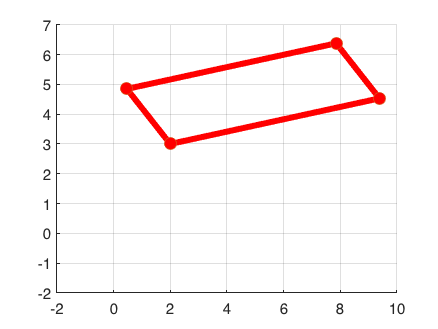


figure
axis([ -2 10 -2 7 ] );
hold on;
% Show the transformed points
plt = plot([X_p(1,:), X_p(1,1)], [X_p(2,:), X_p(2,1)], 'r-', 'linewidth',4);
plot([X_p(1,:), X_p(1,1)], [X_p(2,:), X_p(2,1)], 'o', 'MarkerSize', 8, 'MarkerFaceColor','r');
% Plot transformed shape transparent
%plt.Color(4) = 0.5;
grid on;

Recall that the inverse of the transformation is:

$	\tilde{\bf x} = \left(T_h\,S_h\,R_h\right)^{-1}\,\tilde{\bf x}^\prime
 = R_h^{-1}\,S_h^{-1}\,T_h^{-1}\,\tilde{\bf x}^\prime $.

disp('This is the shape resulting from the inverse affine transformation')

This is the shape resulting from the inverse affine transformation


% Calculate the shape produced by the inverse affine 
Xi = inv(Rh) * inv(Sh) * inv(Th) * X_p 

Xi =          0    4.0000    4.0000    0.0000
         0    0.0000    2.0000    2.0000
    1.0000    1.0000    1.0000    1.0000



% Convert from homogeneous to cartesian coordinates
Xc = [ Xi(1,:) ./ Xi(3,:); Xi(2,:) ./ Xi(3,:)]

Xc =          0    4.0000    4.0000    0.0000
         0    0.0000    2.0000    2.0000


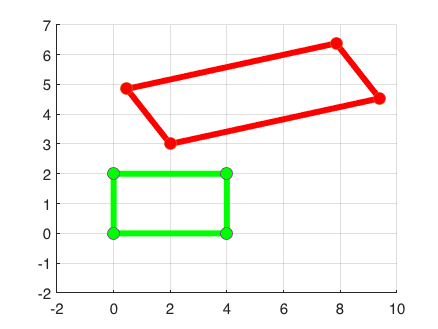


hold on;
% Show the transformed points
plot([Xc(1,:), Xc(1,1)], [Xc(2,:), Xc(2,1)], 'g-', 'linewidth',4);
plot([Xc(1,:), Xc(1,1)], [Xc(2,:), Xc(2,1)], 'o', 'MarkerSize', 8, 'MarkerFaceColor','g');
% Plot transformed shape transparent
grid on;